# Foveal pit shape

This tutorial explains how to compute geometrical features that describe the foveal pit.

The steps followed:

- Load an OCT image into MATLAB

- Flatten the retina (computing total retinal thickness map)

- Rearange sample points into a radial pattern (if needed)

- Compute foveal shape parameters

If you need help please reach out at **dromero@mondragon.edu**

close all; clc; clearvars;
addpath(genpath('../src'));

### Load a file

This step loads the information inside the file and computes the X, Y coordinates of each A-scan.

For foveal analysis we only need the header and segmentation data but we also read B-scans to create some visualizations.

file = '../src/data/raster.vol';
[header, seg, bscan] = read_vol(file, 'get_coordinates');

X = header.X_oct;
Y = header.Y_oct;

### **Flatten the retina**

To flatten the retina we compute the total retinal thickness (TRT).

Therefore, we need to have segmented the inner limiting membrane (ILM) and the Bruch's membrane (BM):

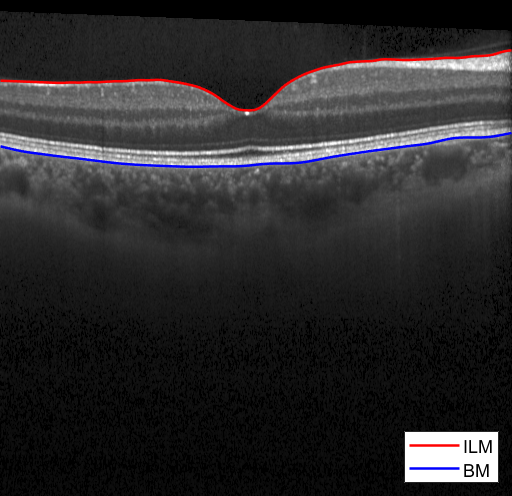

f = figure('Position', [0 0 600 500]);
imshow(bscan(:,:,13)); hold on;

plot(seg.ILM(13,:), 'r', 'LineWidth', 1.5);
plot(seg.BM(13,:),  'b', 'LineWidth', 1.5);
legend({'ILM','BM'}, 'Location', "southeast"); set(gca, 'FontSize', 12);

With segmented data we directly compute the TRT

Thickness = compute_thickness(seg, 'TRT', header.scale_z);
TRT = Thickness.TRT;

We can visualize the obtained TRT profile (for the middle B-scan)

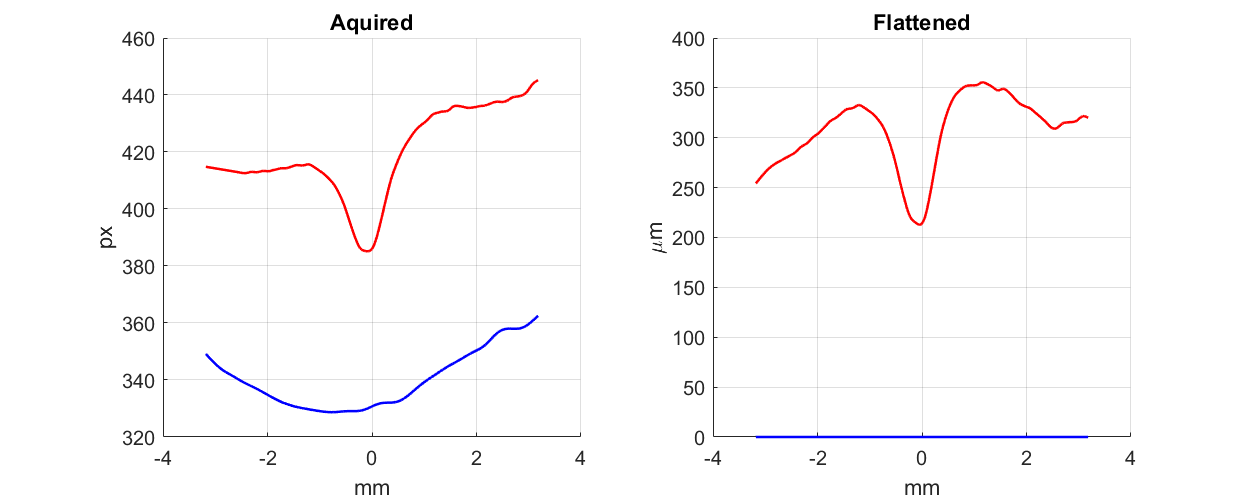

f = figure('Position', [0 0 1000 400]);

subplot(121); hold on;
plot(X(13,:), header.n_axial - seg.ILM(13,:), 'r', 'LineWidth', 1.5);
plot(X(13,:), header.n_axial - seg.BM(13,:), 'b', 'LineWidth', 1.5);
xlabel('mm'); ylabel('px'); title('Aquired');
grid on; set(gca, 'FontSize', 12);

subplot(122); hold on;
plot(X(13,:), TRT(13,:), 'r', 'LineWidth', 1.5);
plot(X(13,:), zeros(1, header.n_ascan), 'b', 'LineWidth', 1.5)
xlabel('mm'); ylabel('\mum'); title('Flattened');
grid on; set(gca, 'FontSize', 12);

Note that the left plot is in pixel units while the second is in micrometers.

### Foveal parameter extraction

[~, rho] = cart2pol(X(13,:), Y(13,:));

parameters = {'rim_height', 'rim_radius', 'mean_slope'};

rho = [rho(257:end); rho(256:-1:1)];
trt = [TRT(13, 257:end); TRT(13, 256:-1:1)];

Z = get_morph_params(rho, trt, parameters)

Z = struct with fields:
    rim_height: 344.1973
    rim_radius: 1.1826
    mean_slope: 6.2606


### Radial analysis

Often, we may be interested in analyzing the foveal shape for different angular directions.

To do this we have two options:

- Acquire radial B-scans

- Interpolate raster B-scans into a radial pattern

Here we explain the second approach.

Supose we have the data used above (25 raster B-scans). We can interpolate it into a radial pattern by:

[X_rad, Y_rad, TRT_rad] = resample_map(X, Y, TRT, 'star', 'max_d', 3, 'n_angle', 20, 'n_point', 100);

We can compare the sampling points

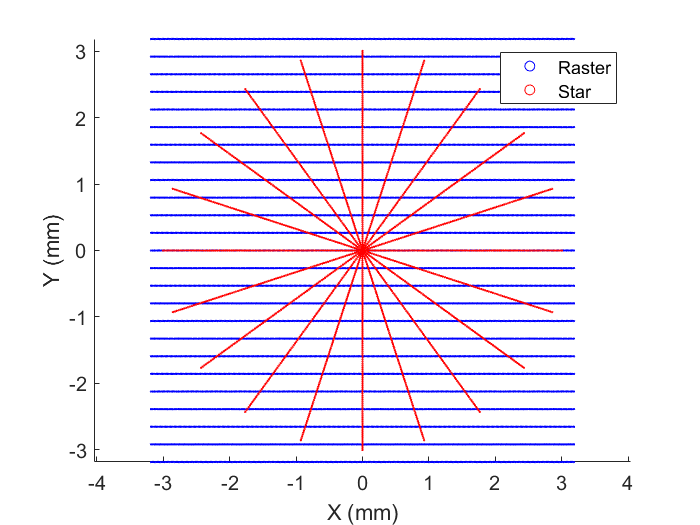

f = figure;
scatter(X(:), Y(:), 1, 'b'); hold on;
scatter(X_rad(:), Y_rad(:), 1, 'r');
axis equal;
xlabel('X (mm)'); ylabel('Y (mm)'); set(gca,'FontSize', 12);
legend({'Raster','Star'});

Now that our data points are in a star pattern it is convenient to transform them to polar coordinates

[theta_rad, rho_rad] = cart2pol(X_rad, Y_rad);

We can also visualize the TRT profiles for every angular direction

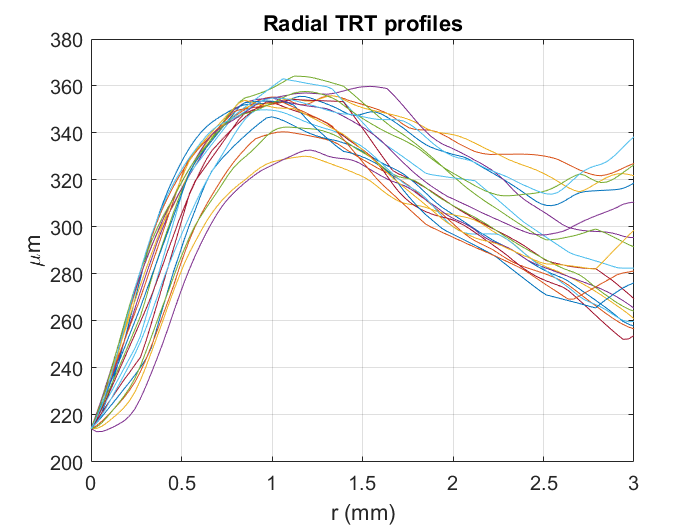

f = figure;
plot(rho_rad(1,:), TRT_rad'); hold on;
xlabel('r (mm)'); ylabel('\mum'); title('Radial TRT profiles'); 
grid on; set(gca,'FontSize', 12);

To compute parameters for every angular direction we use the same function

Z_rad = get_morph_params(rho_rad, TRT_rad, 'all', false)

Z_rad = struct with fields:
                     cft: [214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554 214.1554]
               max_slope: [16.7192 16.6323 15.5662 13.5352 15.1395 14.8241 14.8009 15.1546 13.4349 12.2763 12.6848 12.0566 12.3866 12.2976 12.2091 12.8545 12.9660 14.5104 15.2979 16.0268]
        max_slope_radius: [0.2424 0.2121 0.2121 0.2727 0.3333 0.3333 0.5152 0.3636 0.4848 0.4242 0.4545 0.3636 0.3939 0.4242 0.3333 0.5152 0.1818 0.1818 0.1818 0.2121]
        max_slope_height: [269.0010 264.4034 263.4303 272.5640 277.7494 269.6598 306.5386 256.8301 281.8687 266.0720 263.4005 259.6665 276.4473 289.8735 278.7416 324.7628 254.6848 257.7076 258.3812 265.2431]
     max_slope_disk_area: 0.3598
    max_slope_disk_perim: 2.7451
              mean_slope: [6.9204 5.9999 6.0117 5.3405 7.5840 7.9449 7.0717 7.5180 6.7657 5.5762 5.5555 6.6877 7.9480 7.8879 8.1479 7.

If we only want radial averages just pass true to the last argument

Z_rad_avg = get_morph_params(rho_rad, TRT_rad, 'all', true)

Z_rad_avg = struct with fields:
                     cft: 214.1554
               max_slope: 14.0687
        max_slope_radius: 0.3318
        max_slope_height: 272.8513
     max_slope_disk_area: 0.3598
    max_slope_disk_perim: 2.7451
              mean_slope: 7.1234
              min_height: 214.0940
                pit_area: 0.1319
               pit_depth: 137.4729
              pit_volume: 0.1264
              rim_height: 351.6283
              rim_radius: 1.1121
           rim_disk_area: 3.8572
          rim_disk_perim: 7.5561
